## Load covid_data from mat file

covid_data = load("covid_data.mat").covid_data;

## Loop through covid_data

dates = [];
for i=3:width(covid_data)
    dates = [dates; datenum(covid_data{1,i})];
end

## Create a list of countries

global_data = Global();
total_cases = [];
total_deaths = [];
for i=2:length(covid_data)
    country_name = string(covid_data{i,1});
    if ~isempty(global_data.Countries) && global_data.Countries(end).Name == country_name
        country = global_data.Countries(end);
    else
        country = Country(country_name);
        global_data.Countries = [global_data.Countries; country];
    end
    stateName = string(covid_data{i,2});
    case_deaths = [covid_data{i,3:end}];
    cases = case_deaths(1,1:2:end)';
    deaths = case_deaths(1,2:2:end)';
    if isequal("", stateName)
        stateName = "All";
        total_cases = [total_cases; cases'];
        total_deaths = [total_deaths; deaths'];
    end
    state = State(stateName);
    state.Cases = cases;
    state.Deaths = deaths;
    country.States = [country.States; state];
end
global_data.Cases = sum(total_cases);
global_data.Deaths = sum(total_deaths);

## Plot Cumulative data

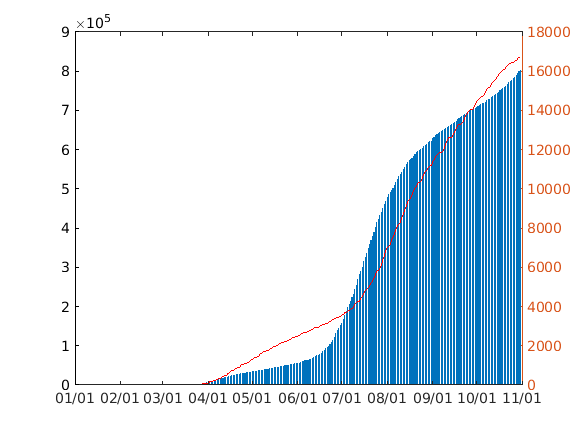

bar(datenum(dates), global_data.Countries(180).States(12).Cases, 0.8)
hold on
yyaxis right
plot(datenum(dates), global_data.Countries(180).States(12).Deaths,"r")
xlim(gca, [dates(1), dates(end)]);
xlim(gca, "manual");
datetick('x', 6)
hold off

## Plot Daily data

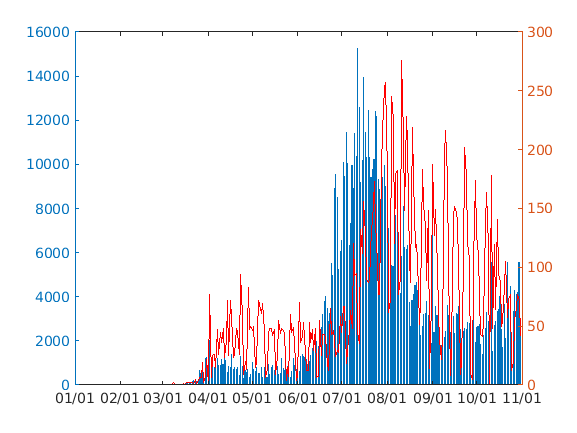

figure(2);
yyaxis left
daily_cases = global_data.Countries(180).States(12).Cases - [0; global_data.Countries(180).States(12).Cases(1:end-1)];
bar(datenum(dates), daily_cases)
hold on
yyaxis right
daily_deaths = global_data.Countries(180).States(12).Deaths - [0; global_data.Countries(180).States(12).Deaths(1:end-1)];
plot(datenum(dates), daily_deaths,"r")
datetick('x', 6)
hold off

## Get the average

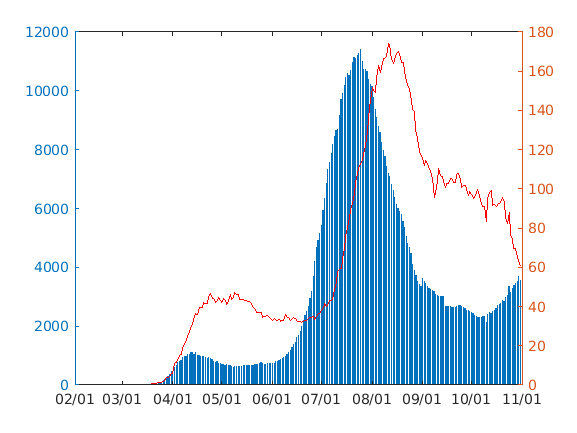

figure(3);
window = 14;
average_cases = movmean(daily_cases,[window-1 0]);
average_deaths = movmean(daily_deaths,[window-1 0]);

stop = length(dates);
inside_dates = window:stop;
partial_dates = dates(inside_dates);
partial_cases = average_cases(inside_dates);
partial_deaths = average_deaths(inside_dates);
yyaxis left
bar(datenum(partial_dates), partial_cases)
hold on
yyaxis right
plot(datenum(partial_dates), partial_deaths,"r")
datetick('x', 6)
hold off